clear; 
close all;
clc;

b) Count the number of blocks of each colour 

%segement image by colour in lab colour space 
img = imread('very_hard.jpg');
lab_img = rgb2lab(img);
ab = lab_img(:,:,2:3);
ab = im2single(ab);
L = imsegkmeans(ab, 11,NumAttempts=11);

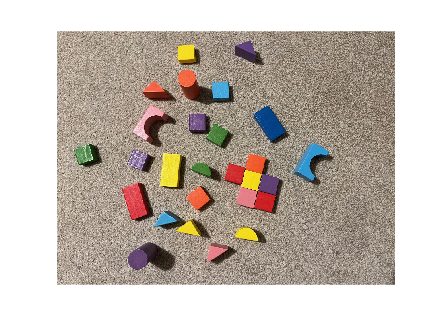

imshow(img)

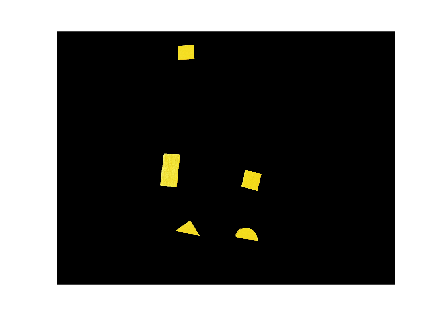

% yellow shapes 
m = L == 3;
cluster3 = img.*uint8(m);
imshow(cluster3)


% preprocess image 
yellow = preProcessImage(cluster3);

% count number of shapes 
blocks = bwconncomp(yellow);
disp('The total number of yellow blocks is  :');

The total number of yellow blocks is  :


disp(blocks.NumObjects);

     5



yellow_blocks = blocks.NumObjects;

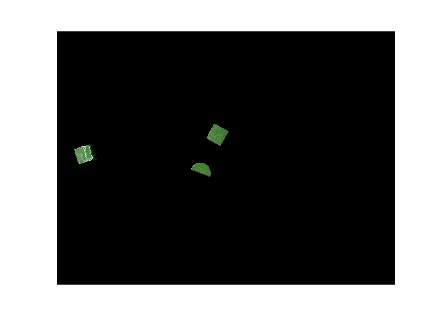

% green shape
m = L == 6;
cluster6 = img.*uint8(m);
imshow(cluster6)


% preprocess image 
green = preProcessImage(cluster6);

% count number of shapes 
blocks = bwconncomp(green);
disp('The total number of green blocks is  :');

The total number of green blocks is  :


disp(blocks.NumObjects);

     3



green_blocks = blocks.NumObjects;

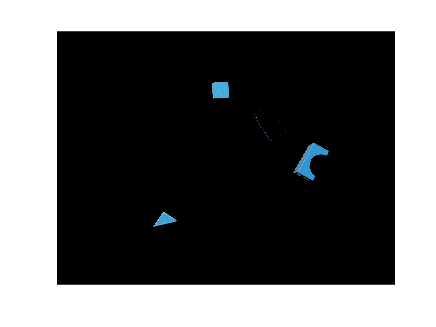

% light blue shapes 
m = L == 7;
cluster6 = img.*uint8(m);
imshow(cluster6)


% preprocess image 
lblue = preProcessImage(cluster6);
lblue = bwareaopen(lblue,1000);

% count number of shapes 
blocks = bwconncomp(lblue);
disp('The total number of light blue blocks is  :');

The total number of light blue blocks is  :


disp(blocks.NumObjects);

     3



lb_blocks = blocks.NumObjects;

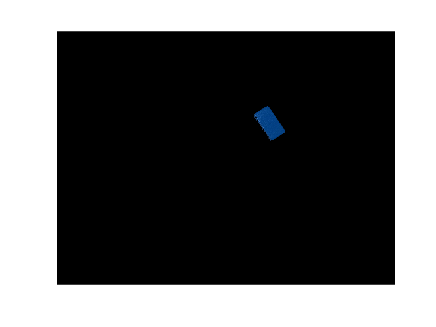

% dark blue
m = L == 4;
cluster3 = img.*uint8(m);
imshow(cluster3)


% preprocess image 
dblue = preProcessImage(cluster3);

% count number of shapes 
blocks = bwconncomp(dblue);
disp('The total number of dark blue blocks is  :');

The total number of dark blue blocks is  :


disp(blocks.NumObjects);

     1



db_blocks = blocks.NumObjects;

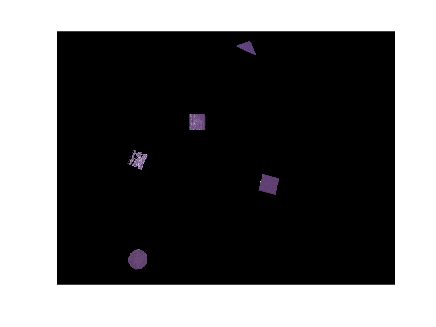

% purple blocks 
m = L == 11;
cluster9 = img.*uint8(m);
imshow(cluster9)

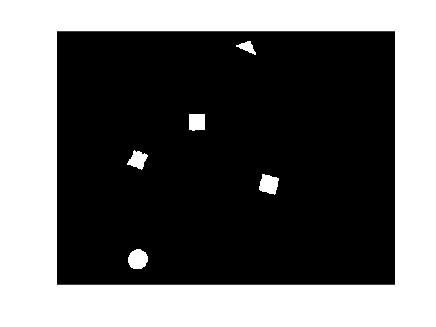


% preprocess image 
purple = preProcessImage(cluster9);
se = strel('disk', 6);
closedImage = imclose(purple, se);
purple = imfill(closedImage, 'holes');
imshow(purple)


% count number of shapes 
blocks = bwconncomp(purple);
disp('The total number of purple blocks is  :');

The total number of purple blocks is  :


disp(blocks.NumObjects);

     5



purple_blocks = blocks.NumObjects;

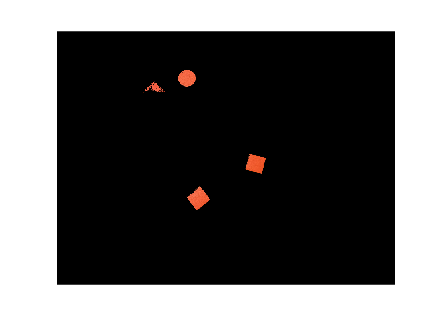

% red and orange shapes 
m = L == 2;
cluster1 = img.*uint8(m);
imwrite(cluster1, 'red_orange.png')

i = imread('red_orange.png');
lab_img = rgb2lab(i);
ab = lab_img(:,:,2:3);
ab = im2single(ab);
RG5 = imsegkmeans(ab, 5,NumAttempts=5);
RG4 = imsegkmeans(ab, 4,NumAttempts=4);

m = RG4 == 4;
cluster7 = img.*uint8(m);
imshow(cluster7)

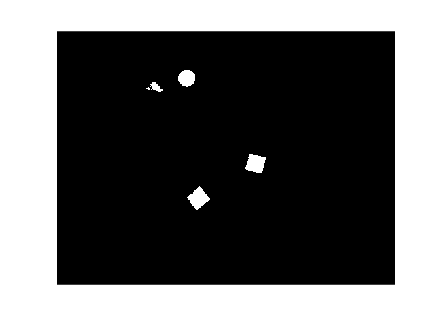

% orange 
% preprocess image 
orange = preProcessImage(cluster7);
imshow(orange)

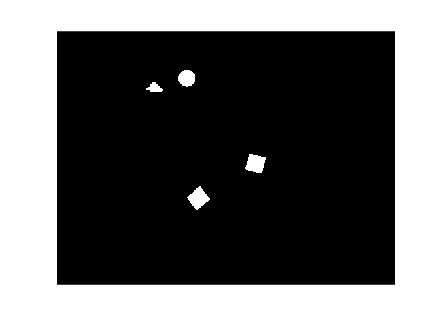

se = strel('disk', 7);
closedImage = imclose(orange, se);
orange = imfill(closedImage, 'holes');
imshow(orange)


% count number of shapes 
blocks = bwconncomp(orange);
disp('The total number of orange blocks is  :');

The total number of orange blocks is  :


disp(blocks.NumObjects);

     4



orange_blocks = blocks.NumObjects;

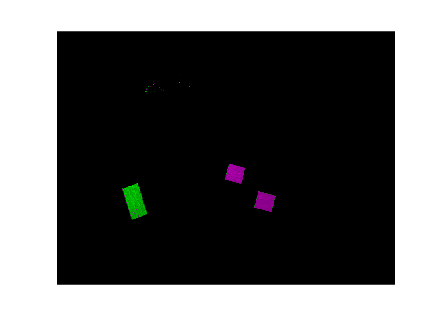

% red
m = RG5 == 3;
red_pt1= img.*uint8(m);

m = RG5 == 4;
red_pt2 = img.*uint8(m);

R = imfuse(red_pt1,red_pt2);
imshow(R)

red = preProcessImage(R);

% count number of shapes 
blocks = bwconncomp(red);
disp('The total number of red blocks is  :');

The total number of red blocks is  :


disp(blocks.NumObjects);

     3



red_blocks = blocks.NumObjects;

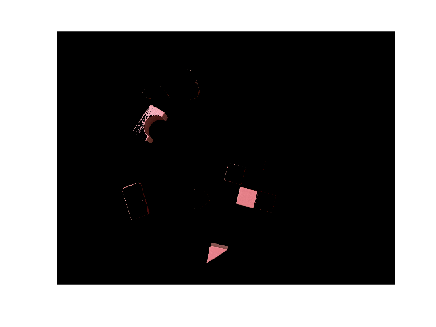

% pink shape 
m = L == 5;
cluster4 = img.*uint8(m);
imwrite(cluster4, 'pink_orange.png');

i = imread('pink_orange.png');
lab_img = rgb2lab(i);
ab = lab_img(:,:,2:3);
ab = im2single(ab);
PO = imsegkmeans(ab, 3,NumAttempts=3);

m = PO == 3;
cluster7 = img.*uint8(m);
imshow(cluster7);

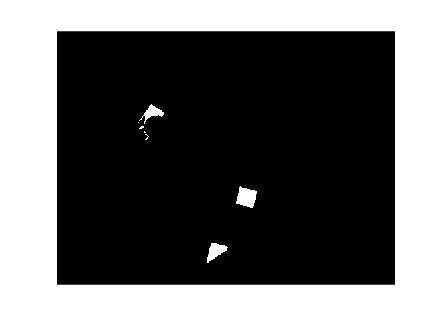


% preprocess image 
pink = preProcessImage(cluster7);
se = strel('disk', 5);
closedImage = imclose(pink, se);
pink = imfill(closedImage, 'holes');
pink = bwareaopen(pink,1000);
imshow(pink)


% count number of shapes 
blocks = bwconncomp(pink);
disp('The total number of pink blocks is  :');

The total number of pink blocks is  :


disp(blocks.NumObjects);

     3



pink_blocks = blocks.NumObjects;

a) Count the total number of blocks 

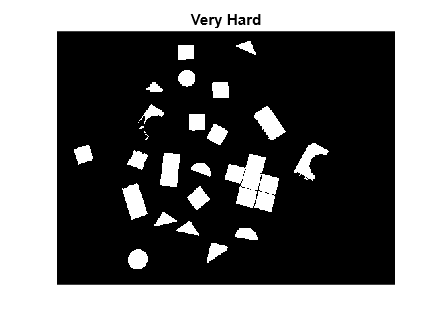

%fuse all coloured shapes into one image 
C = imfuse(yellow,red);
C = imfuse(C,lblue);
C = imfuse(C,dblue);
C = imfuse(C,purple);
C = imfuse(C,green);
C = imfuse(C,orange);
C = imfuse(C,pink);

% preprocess image 
img_gray = rgb2gray(C);
BW1 = imbinarize(img_gray);
imshow(BW1)
title('Very Hard')

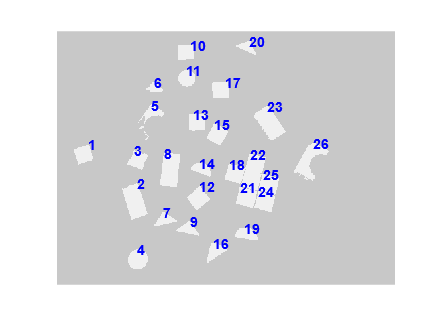

vislabels(BW1)

% count number of blocks
blocks = bwconncomp(BW1);
disp('The total number of blocks is  :');

The total number of blocks is  :


%disp(blocks.NumObjects);

total_blocks = yellow_blocks + db_blocks + lb_blocks + red_blocks + orange_blocks + green_blocks + pink_blocks + purple_blocks;
disp(total_blocks);

    27



d) Number of blocks of each shape of the same colour 

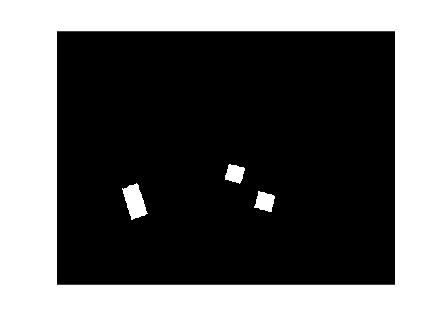

% red 
BW = red;
imshow(red)

[shapeStruct, red_shapes] = classifyBlocks(BW);
disp('The total number of blocks of each shape that are red are   :')

The total number of blocks of each shape that are red are   :


disp(shapeStruct);

    Rectangle: 1
       Square: 2



disp(red_shapes);

    {'Rectangle'}    {'Square'}    {'Square'}



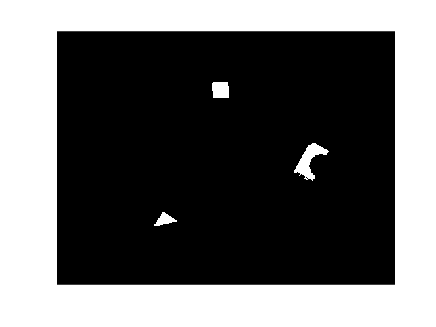

% light blue
BW = lblue;
imshow(BW)

[shapeStruct, lb_shapes] = classifyBlocks(BW);
disp('The total number of blocks of each shape that are light blue are   :')

The total number of blocks of each shape that are light blue are   :


disp(shapeStruct);

      Bridge: 1
      Square: 1
    Triangle: 1



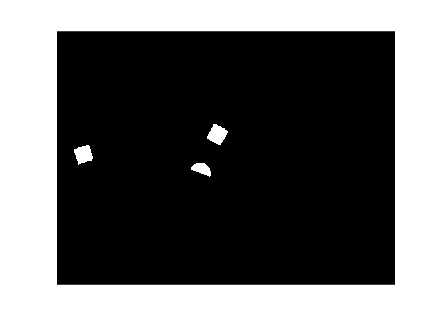

% green 
BW = green;
imshow(BW)

[shapeStruct, green_shapes] = classifyBlocks(BW);
disp('The total number of blocks of each shape that are green are   :')

The total number of blocks of each shape that are green are   :


disp(shapeStruct);

    Semicircle: 1
        Square: 2



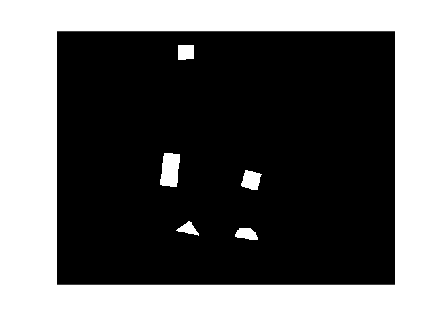

% yellow
BW = yellow;
imshow(BW)

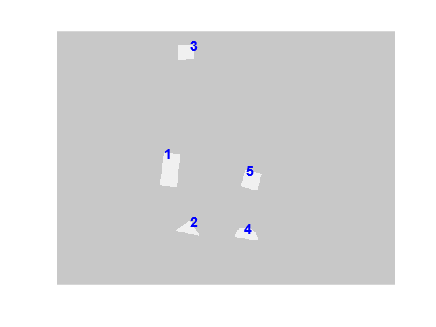

vislabels(BW)

[shapeStruct, yellow_shapes] = classifyBlocks(BW);
disp('The total number of blocks of each shape that are yellow are   :')

The total number of blocks of each shape that are yellow are   :


disp(shapeStruct);

        Circle: 1
     Rectangle: 1
    Semicircle: 1
        Square: 1
      Triangle: 1



% purple
BW = purple;
imshow(BW)

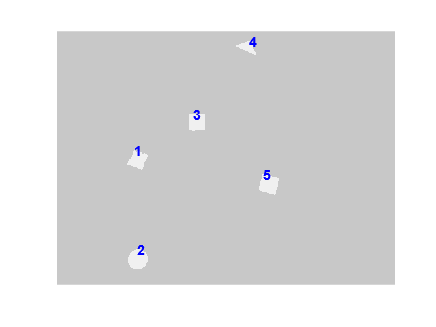

vislabels(BW)

[shapeStruct, purple_shapes] = classifyBlocks(BW);
disp('The total number of blocks of each shape that are purple are   :')

The total number of blocks of each shape that are purple are   :


disp(shapeStruct);

      Circle: 2
      Square: 2
    Triangle: 1



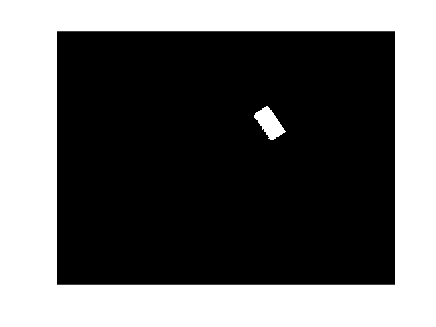

% dark blue 
BW = dblue;
imshow(BW)

[shapeStruct, db_shapes] = classifyBlocks(BW);
disp('The total number of blocks of each shape that are dark blue are   :')

The total number of blocks of each shape that are dark blue are   :


disp(shapeStruct);

    Rectangle: 1



% orange 
BW = orange;
imshow(BW)

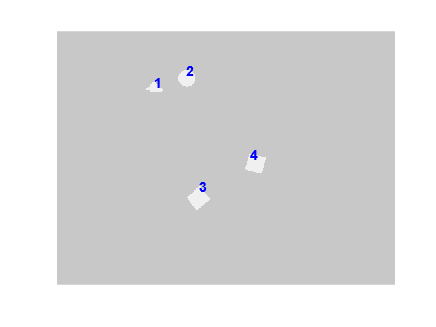

vislabels(BW)

[shapeStruct, orange_shapes] = classifyBlocks(BW);
disp('The total number of blocks of each shape that are orange are   :')

The total number of blocks of each shape that are orange are   :


disp(shapeStruct);

        Circle: 1
    Semicircle: 1
        Square: 2



% pink
BW = pink;
imshow(BW)

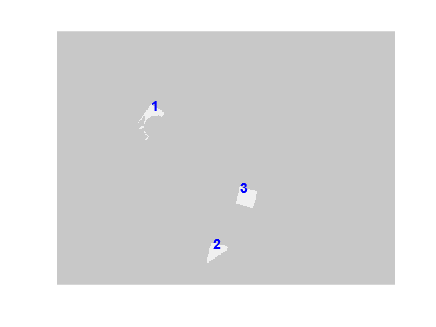

vislabels(BW)

[shapeStruct, pink_shapes] = classifyBlocks(BW);
disp('The total number of blocks of each shape that are pink are   :')

The total number of blocks of each shape that are pink are   :


disp(shapeStruct);

      Bridge: 1
      Square: 1
    Triangle: 1



c) Count number of blocks of each shape

all_shapes = [lb_shapes,db_shapes, pink_shapes, orange_shapes, purple_shapes, yellow_shapes, green_shapes, red_shapes, pink_shapes];

[uniqueShapes, ~, idx] = unique(all_shapes);
shapeCounts = histcounts(idx, 1:length(uniqueShapes)+1);
shapeStruct = struct();
for i = 1:length(uniqueShapes)
    shapeStruct.(uniqueShapes{i}) = shapeCounts(i);
end
disp('The total number of each shape is  :')

The total number of each shape is  :


disp(shapeStruct)

        Bridge: 3
        Circle: 4
     Rectangle: 3
    Semicircle: 3
        Square: 12
      Triangle: 5



function new_img = preProcessImage(img)
    img_gray = rgb2gray(img);
    BW1 = imbinarize(img_gray);
    BW2 = imfill(BW1,'holes');
    new_img = bwareaopen(BW2,100);
end
function [shapeStruct, shapes] = classifyBlocks(BW)
    shapes = {};
    % identifies boundary of each object (B = boundaries),(L = labels objects and holes),(N = number of objects), 
    [B,L,N] = bwboundaries(BW);

    % calculate properties of all shapes and store in an array 
    stats =  regionprops(L, 'Area', 'Perimeter');
    area = cat(1, stats.Area);
    perimeter = cat(1,stats.Perimeter);
  
    for k=1:N
        % calculate smallest bounding box of object 
        boundary = B{k};
        [rx,ry,boxArea] = minboundrect( boundary(:,2), boundary(:,1));
        width = sqrt( sum( (rx(2)-rx(1)).^2 + (ry(2)-ry(1)).^2));
        height = sqrt( sum( (rx(2)-rx(3)).^2+ (ry(2)-ry(3)).^2));
        aspectRatio = width/height;

        if aspectRatio > 1
           aspectRatio = height/width;  %make aspect ratio less than unity
        end
        
        p = perimeter(k);
        a = area(k);

        % check if circle
        if ((p.^2)./(4*pi*a)) < 1.2
            shapes{end+1} = 'Circle';
        elseif (area(k)/boxArea) > 0.85
            if aspectRatio > 0.80
                shapes{end+1} = 'Square';
            else
                shapes{end+1} = 'Rectangle';
            end
        else
            if ((p.^2)./(4*pi*a)) > 2
                shapes{end+1} = 'Bridge';
            elseif (area(k)/boxArea) < 0.6
                shapes{end+1} = 'Triangle';
            else
                shapes{end+1} = 'Semicircle';
            end
        end 
    end 
    % display the number of blocks of each shape 
    [uniqueShapes, ~, idx] = unique(shapes);
    shapeCounts = histcounts(idx, 1:length(uniqueShapes)+1);
    shapeStruct = struct();
    for i = 1:length(uniqueShapes)
        shapeStruct.(uniqueShapes{i}) = shapeCounts(i);
    end
end

filling in shapes may be making them inaccuate 

correct counting of shapes 

occasional incorrect identification 